# Feedback FOPDT Models

Daniel Anthony Barrett

21 June 2023

Final Year Project (C) 478

Supervisor: Dr Cripwell

### Feedback FOPDT Models

Fit FOPDT models to the copper solvent extraction model to use for the feedback controller tuning

## Setup

### MATLAB Simulink

clear;
clc;
gamma_max = 2000; 

### Plot colours

maroon = '#A2142F';
blue   = '#0072BD';

## Step in v_LE

### Read data

vLE_step_data = readtable('controller_tuning\data\feedback\vLE_step_feedback.csv');

### Extract data

% model time
vLE_step.time = vLE_step_data.Time; 

% valve position data
vLE_step.vLE = vLE_step_data.vLE_control;
vLE_step.vLO = vLE_step_data.vLO_control;

% controlled variables data
vLE_step.cLO = vLE_step_data.cLO_measured;
vLE_step.cRE = vLE_step_data.cRE_measured;

### Preprocess

% deviation variable form
vLE_step.vLE_prime = vLE_step.vLE-vLE_step.vLE(1);
vLE_step.vLO_prime = vLE_step.vLO-vLE_step.vLO(1);
vLE_step.cLO_prime = vLE_step.cLO-vLE_step.cLO(1);
vLE_step.cRE_prime = vLE_step.cRE-vLE_step.cRE(1);

% time step size
vLE_step.deltaT = vLE_step.time(2) - vLE_step.time(1);

% time in hours
vLE_step.timeH = vLE_step.time/(60*60);

### cLO change

### FOPDT model

for gamma = 0:gamma_max
    
    % system set up
    vLE_step.A = [vLE_step.cLO_prime((1+gamma):(end-1)), vLE_step.vLE_prime(1:(end-1-gamma))];
    vLE_step.z = vLE_step.cLO_prime((2+gamma):end);
    
    % linear regression
    w = vLE_step.A\vLE_step.z;
    a = w(1);
    b = w(2);
    
    % calculate predicted values
    vLE_step.cLO_p = vLE_step.A*w;
    
    % calculate MSE 
    vLE_step.MSE_cLO(gamma+1) = mean((vLE_step.cLO_p - vLE_step.z).^2);
    
    % calculate transfer function 
    vLE_step.Kp_cLO(gamma+1) = b/(1-a);
    vLE_step.tau_cLO(gamma+1) = -vLE_step.deltaT/log(a);
    vLE_step.theta_cLO(gamma+1) = gamma*vLE_step.deltaT;
end

#### Find optimal gamma values

% index of optimal gamma
vLE_step.opt_gamma_index_cLO = find(vLE_step.MSE_cLO == min(vLE_step.MSE_cLO));
% optimal transfer function values
vLE_step.opt_gamma_cLO = vLE_step.opt_gamma_index_cLO - 1;
vLE_step.opt_Kp_cLO = vLE_step.Kp_cLO(vLE_step.opt_gamma_index_cLO);
vLE_step.opt_tau_cLO = vLE_step.tau_cLO(vLE_step.opt_gamma_index_cLO);
vLE_step.opt_theta_cLO = vLE_step.theta_cLO(vLE_step.opt_gamma_index_cLO);

#### Simulate transfer function on Simulink

% setup simulink transfer function values
simulink_Kp = vLE_step.opt_Kp_cLO;
simulink_tau = vLE_step.opt_tau_cLO;
simulink_theta = vLE_step.opt_theta_cLO;

% run Simulink model
simulink_input = [vLE_step.time vLE_step.vLE_prime];
simulink_output = sim('controller_tuning\FOPDT_models\FOPDT_model.slx');

% extract Simulink results
vLE_step.FOPDT_fit_cLO = simulink_output.results.Data;
vLE_step.FOPDT_time_cLO = simulink_output.tout;
vLE_step.FOPDT_timeH_cLO = simulink_output.tout/(60*60);

#### Plot cLO response to vLE change

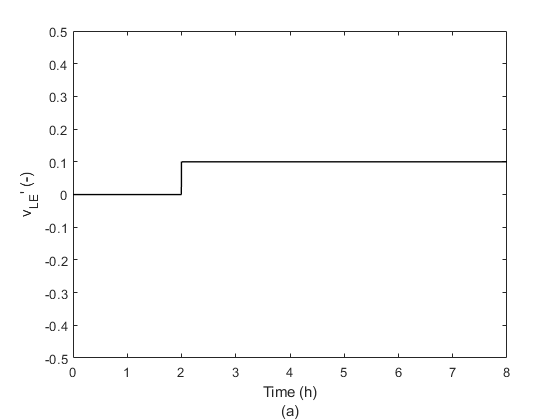

figure(1);

% plot vLE
tiledlayout(3,1);
plot(vLE_step.timeH, vLE_step.vLE_prime, 'k-', 'LineWidth', 1);
xlabel(["Time (h)";"(a)"]);
ylabel("v_{LE}' (-)");
xlim([0 vLE_step.FOPDT_timeH_cLO(end)]);
ylim([-0.5 0.5]);

% plot cLO measured
nexttile;

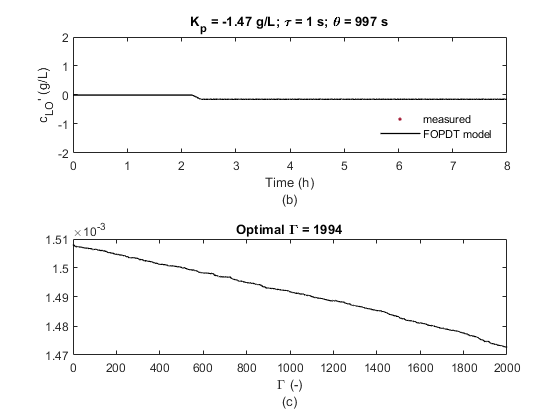

plot(vLE_step.timeH, vLE_step.cLO, '.', 'MarkerSize', 6, 'Color', maroon);
hold on
plot(vLE_step.FOPDT_timeH_cLO, vLE_step.FOPDT_fit_cLO, 'k-', 'LineWidth', 1);
hold off
vLE_step.cLO_title = sprintf('K_p = %.2f g/L; \\tau = %.0f s; \\theta = %.0f s', vLE_step.opt_Kp_cLO, vLE_step.opt_tau_cLO, vLE_step.opt_theta_cLO);
title(vLE_step.cLO_title);
legend({'measured', 'FOPDT model'}, 'Location', 'southeast');
legend('boxoff');
xlabel(["Time (h)";"(b)"]);
ylabel("c_{LO}' (g/L)");
xlim([0 vLE_step.FOPDT_timeH_cLO(end)]);
ylim([-2 2]);

% plot MSE
nexttile;
plot([0:gamma_max], vLE_step.MSE_cLO, 'k-', 'LineWidth', 1);
vLE_step.cLO_MSE_title = sprintf('Optimal \\Gamma = %.0f', vLE_step.opt_gamma_cLO);
title(vLE_step.cLO_MSE_title);
xlabel(["\Gamma (-)"; "(c)"]);
xlim([0 gamma_max]);